# Living with MATLAB

*A Guide with Tips, Tricks and Some Good Practices *

*by Oğul Can Yurdakul, METU EEE*

*Version 3, Last updated on 21.03.2022*

## I. MATLAB in General

**Brushing up on your MATLAB syntax.** Before going into this tutorial, you should know the basics of coding in MATLAB, as it builds on that knowledge further on. Some of these basics are the following:

- Creating, manipulating, indexing and slicing vectors (1D arrays) & matrices (2D arrays)

- Control and loop commands: `if`, `while`, `for`

- Writing custom functions

One resource provided by MATLAB is [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), which is an introductory course on MATLAB covering the basics. The additional benefit of MATLAB Onramp is that it also gives a completion certificate, which is always nice to have (especially if you are hunting for internships).

**Beyond syntax.** Coding is much more than just knowing the syntax. Simply knowing how certain basic commands are written and executed in the MATLAB syntax is essential, but it is up to you as the coder to figure out how a verbally or mathematically specified problem should be coded. Some basic questions could be the following:

- What data structures do I need? Will regular arrays suffice, or do I need cell arrays, structs, etc.? Should I create my own, composite data structures out of the existing basic ones?

- What is the basic flow of the algorithm I am supposed to implement? What are the basic checks and computations that need to be performed?

- How does the problem decompose itself into smaller subproblems? What should be their appropriate inputs and outputs? (more in Section II.1)

- What are my computational constraints? How much computational power can I use, and how long is the program allowed to run?

- How should a user interact with my code? Does it need a Graphical User Interface (GUI) or can I make the user efficiently interact with the code via the command line?

These are just some of the basics that come to my mind right now, and I have no doubt the list above is not exhaustive. But my point is this: Learning how to think about and answer these questions requires *practice.* You don't read your way into it.

One cool tool for practicing your MATLAB coding skills can be [MATLAB Cody](https://www.mathworks.com/matlabcentral/cody/), a gamified problem solving service provided by MATLAB. It also has problem groups specific to different topics, such as combinatorics or vector computations (not to be confused with vectorizing your code). It could be fun, go check it out.

**Finding help.** The very first thing you should know about any programming language/environment is where to find help. MATLAB is a very strong language in that front, due to its popularity. It is extensively documented, with in-line help texts and documentation pages offline. The fastest way to get to them is through the command window:

- `help <function name>` brings the help text accompanying the function. This should your first attempt at figuring out how a function works.

- `doc <function name>` opens the documentation of your function in a pop-up window, which is the same documentation you will find online (i.e. no need for opening up your browser). I recommend you go this way usually after trying `help` first, as the documentation is much longer and extensive, although much more user-friendly and clickable.

- `lookfor <keyword>` is usually unknown, with good reason. It searchs for the `keyword` in the whole documentation/help texts of MATLAB, and will give you any match it gets, although I assume the search can be refined. (Check the help/documentation of `lookfor`!) It is like a Google Search but in MATLAB, and will give you tons of functions. 

Aside from these function helps, if you just don't know how to do/code something in MATLAB, do the first thing that I am sure came to your mind:

Google Search "`<thing>` in matlab"

The MATLAB/Mathworks Community is immense, and somebody has most likely asked the same or a very similar question before. Don't bother reinventing the wheel (but also don't plagiarise!).

**Relatively new facilities of MATLAB. **As it is a widely-used programming language, MATLAB is constantly updated with new and useful facilities. I highly recommend you always use the latest available version (MATLAB will let you know when they're out), which is currently 2022a, because they not only improve the GUI or whatever but also they syntax. The three latest improvements I find useful are the following

- MATLAB syntax now has the `switch`-`case` structure you most likely encountered in other languages, which saves you from using a bunch of `if` statements.

- Function variables can now be declared in the usual `variableName=value` format when calling a function, instead of the previous name-value pair syntax of `'variableName', value`.

- The MATLAB GUI now supports autocomplete, which helps greatly for quick coding.

After registering with your METU mail and the school's MATLAB license on the Mathworks website, you will get access to the following tools:

- [MATLAB Drive](https://www.mathworks.com/products/matlab-drive.html) is the cloud storage service of MATLAB. There is no obligation to store MATLAB-related files exclusively, but as the capacity is somewhat limited that is how you should proceed. 

- [MATLAB Mobile](https://www.mathworks.com/products/matlab-mobile.html) is the mobile application of MATLAB (iOS & Android), and I find it mostly useful for its command line rather than scripting actual code. It integrates well with MATLAB Drive, and so you can run your code stored there on your mobile. It can also store data from the sensors on your phone, which can also come in handy in various projects.

- [MATLAB Online](https://matlab.mathworks.com) is the way to go if you don't want to download many GBs of MATLAB to your computer, it is like Google Colab but for MATLAB. You can write codes & Live Scripts in MATLAB and run them, but will be limited by your Internet connection. MATLAB Online also integrates automatically with MATLAB Drive.

**MATLAB is a very high-level language. **As a last warning in general about MATLAB, I should mention that MATLAB is a very high-level language, meaning it may not always do what you think it does. You should always check the documentation of the functions you are using. The code you write may seem to be working, i.e. it may compile and run and produce some output, but it may not work they way you want it to, simply because a function does its taks in an unexpected way under the hood.

## II. Coding and Report Writing in MATLAB

The quick summary of this whole section is 

*Write **working** code that you would **want to read and understand**.*

You can take this as me asking for a "personal favor" from you on behalf of all the TAs and instructors, or anybody who might have/want to read your codes and reports. Keeping this motto in mind will not only help your future graders immensely, but also help *you* write better working/looking code and think more coherently when doing so. 

### II.1. Clean & Legible Code

**Starting Clean & Continuing So.** How you start writing your code is usually how you finish it: Start messy and you will end up with terrible looking code. Start clean and it will remain clean. So let's start clean, by cleaning everything in the way.

clearvars; close all; clc;

This may look redundant, as it looks like you are cleaning what is already clean. But when you run your code consecutively (as one often does) without such a quick clean up, you risk carrying over the variables from your previous run. At best, your code will throw an error and you will notice what is wrong. At worst, your code will run when it isn't supposed to: You may have adjusted a variable here and there to make it work along the way, and so the code appears to work when you run it the second time.

MATLAB is insensitive to white space, unlike some other languages out there. This is a great benefit: You can add white space anywhere to make your code more legible. Consider the following, very simplistic examples: Which one is better? This one:

or, this one:

The second one takes much more space, but isn't it much easier on the eyes? They both do the exact same computation in the exact same manner, so we don't lose anything in terms of functionality, but gain a ton on the legibility front. This helps you make sense of your code, and more importantly spot any error much more quickly.

Secondly: Name your variables meaningfully. MATLAB absolutely does not care what you name your variables as long as it is [valid](https://www.mathworks.com/help/matlab/matlab_prog/variable-names.html), and it allows for a wide range of variable names as it is also case sensitive. It may be gibberish or a line from Shakespeare, they are all the same in the eye of the compiler. So, why not name your variables in a more descriptive manner, so that you understand what they are more quickly? For example, if you are computing the mean of your random samples, don't opt for an onverly simplistic 

but instead for

or for

The first convention is called the *camel case*, and the second one is the *snake case*. You don't have to choose one or the other either. You can use the underscore to stand for a subscript, too: For example if you have two random variables $X_1$and $X_2$, naming their sample means as `sampleMean_1` and `sampleMean_2` would make quite a lot of sense. The other extreme would be to make the variable names *too explanatory*, like

It is an exaggerated example, but it serves to show how much is too much. In short, keep your variable names short but descriptive to quickly understand what they are further on in the code.

**Helping Yourself.** As you continue your education or work, your codes will only get more complicated and long, so it is important you know how to help your future. Your code makes a ton of sense as you are writing it in the moment, but trust me, it will look like absolute nonsense after some time. If you don't explain to yourself

- what variable contains what, 

- how your functions work, 

- what quantitiy is being computed in one run of the for loop,

etc., you will have to put an unnecessary amount of work in the future. For example, if I compute a series of quantities that depend on one another in a for loop for a range of parameters, some quick commenting like

helps 

- you have a better mental image of what is actually happening in the loop, hence allowing you to code and debug faster, and helps 

- other readers of your code make sense of it much quicker. 

If you are having further troubles with your code, you might try some documented [rubber duck debugging](https://www.wikiwand.com/en/Rubber_duck_debugging) by explaining what happens at each line to a virtual (or real) rubber duck.

You will also often write functions of your own to help your computation, the utility of which I will mention in the following subsection. Adding help texts to your functions will help you understand what they do at a quick glance, without opening and reading the function definition all over again. For example, here is the help text of a Bernoulli variable sampler I wrote:

% help Bernoulli

It is quick and effective. Helps a ton. (The above line is commented out as help texts at the ends of files are not supported, so MATLAB prints some other `bernoulli` function's help text. You can refer to the Appendix to see how help texts in `.m` file functions are written.)

**Modularity & Sectioning.** The problems that you will have to solve via coding in any environment will usually be immense, and will only get bigger in time. Tackling the whole problem at once will almost always be very difficult, if not altogether impossible. Therefore, you should be able to *separate the problem into smaller, sub-problems.* This has two main advantages:

- The big and scary problems will turn into much more manageable, smaller problems. Less adrenalin, more control.

- More importantly, because you will be going one sub-problem at a time, it will be easier to identify which of your sub-solutions is malfunctioning when there is something wrong with the overall code. On the positive side, as you progress upwards from smaller problems to the bigger ones, you will be relying safely on the well-working of the smaller components of bigger programs, allowing you to not think about everything at ones but work in abstractions.

A great way to modularize your code is using the sectioning utility of MATLAB. In `.m `files and `.mlx` files alike, MATLAB allows you to separate your code into sections which can be run individually. This way, when you just want to change one small bit at the end, you don't have to run eeeverything from the beginning, but only the last section (it is especially useful when prettifying figures). In a `.m` file, this works as follows:

The two consecutive percent signs `%%` tells MATLAB at which line a new section begins. In a Live Script, you can do this via the toolbar or by `Ctrl+Alt+Enter`. 

Arranging your sections according to the parts of a homework for you, should make quite a lot of sense. Having your sections correspond to the smaller sub(sub)-problems that you want to solve will help you diagnose which section is doing well/bad in what way, because you will be able to *run your sections in whichever order you like (i.e. non-sequentially)*. **Beware**: This is a blessing as well as a curse. Again, you risk carrying over variables from one section to the other, which may scramble with your program. As long as you are careful and `clearvars` whenever needed, it is a powerful tool.

### **II.2. Explanatory & Exploratory Code: Live Scripts**

As you write your code, you will often have to wrok through some trial and error and make some exploration and explanation. I find MATLAB Live Scripts help a great deal in doing so, i.e. in writing explorable & self-explaining code. You can document what you find, do and obtain, in the same document as your code lives. If you have used Jupyter Notebooks or Google Colab for Python, this is a very good counterpart of them in MATLAB.

**Text tab.** The toolbar changes to the following look when you open a Live Scripts document.

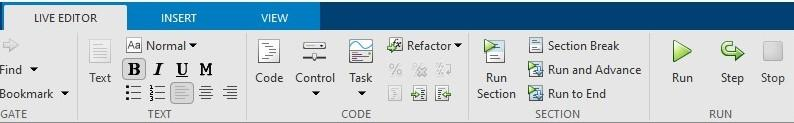

The Text section allows some simple manipulations to your text, such as adding titles and 3 levels of headers. You can have your text **bold**, *italic,* underlined and `monospaced` (for in-line codes), aligned in various manners, in

- bullet 

- points

or in 

- numbered

- lists

and even add some math if you know TeX markup:


$$P(A|B) = \frac{P(B|A)P(A)}{P(B)}$$


These help you write clean explanations for your code. You can add images and a table of contents based on your headers, and also choose where to view you output through the three options indicated below:

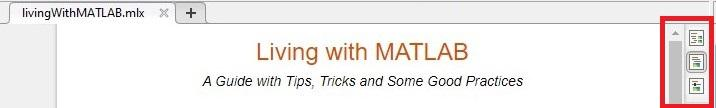

**Code tab.** The main use I make of the Code section is the controls and the section breaks. Take the following code piece, where I plot a vector on the plane.

indexVariable = 2.03;
y = -6.24;
reflect = true;

figure
    if reflect
        plot([0 -indexVariable], [0 -y], 'bx-')
    else
        plot([0 indexVariable], [0 y], 'bx-')
    end
    
    title(['My vector X = (' num2str(indexVariable, '%.2f') ', ' num2str(y, '%.2f') ')'])
    xlim([-10 10]); ylim([-10 10]);
    xlabel('x'); ylabel('y');

You get to enter new values to my variables through a modular GUI interface that is very intuitive to use: It works the same way as if you have written that value there. This allows you to explore variables values within the bounds you specify, without typing and running and retyping and rerunning. Sectioning is quite important for controls: They determine what to compute (if you choose to) upon a change in their value.

**Animations.** You may also choose to observe how certain values effect your outputs in motion. You can do this by repeatedly plotting on the same figure with some delay between the figures. Without the delay between the "frames", MATLAB will show only the end result. Here's an example:

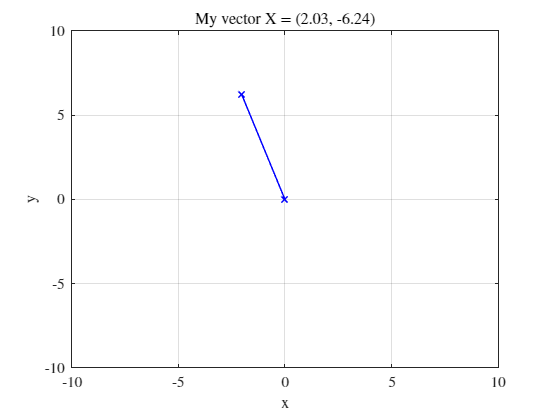

% Create a figure in the variable animFig, so that I can refer to it by name
animFig = figure; 

for theta = (-2:0.01:2) * pi

    figure(animFig) % Current figure is animFig
    plot([cos(theta) cos(theta*1.1) cos(theta*1.2) cos(theta)], ...
        [sin(theta) sin(theta*1.5) sin(theta*1.6) sin(theta)], ...
        '.-') % Plot the plot
    title('Look at my moving triangle!')
    xlim([-1.5 1.5]); ylim([-1.5 1.5]);
    xlabel('x'); ylabel('y');
    pause(0.001) % Pause between frames

end

After playing it once in a Live Script, MATLAB will allow you  

- to play your animation in different speeds *without going through the same computations again*, 

- rewind to specific points,

- adjust playing speed, and 

- save it in various video formats (.gif, .avi and .mp4).

### II.3. Efficient & Debugged Code

**Vectorization.** MATLAB is a programming language that is optimized for operating on/with vector and matrix quantities, so whenever possible, you should vectorize your code. Again, a very simple example is the contrast between the following two codes, that apply the `sign()` function to a vector `x`.

Not vectorized:

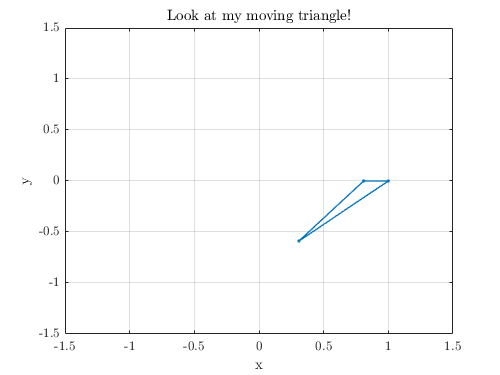

x = -2:2;
res = zeros(size(x)); % Store the result here

for k = 1:length(x)
    display(['Doing loop ' num2str(k) ' of ' num2str(length(x))])
    res(k) = sign(x(k)); % Loop the loop
end
res

As opposed to, vectorized:

x = -2:2;

res = sign(x)

Same result, quicker code, no unnecessary loops. This can help immensely if you are working with large vectors & matrices, and most MATLAB functions have some vector-matrix interpretation of their inputs built-in.

Vectorization also applies to loops: Notice how I use a row vector `1:length(x)` in the loop above, and MATLAB goes over its entries. Well, not really. MATLAB goes over its *columns* as it progresses through the loops, meaning the loop variable is set to the columns of the index vector. A very simple example is the following:

indexVector = magic(3) % Magic matrix generator in MATLAB,
for indexVariable = indexVector
    display(indexVariable)
end

Doing loop 1 of 5
Doing loop 2 of 5
Doing loop 3 of 5
Doing loop 4 of 5
Doing loop 5 of 5


If you have multiple parameters to go through, this can help you write concise and effective code easily. It's all up to your imagination.

A final word about vectorization: Don't overuse or force it too much. If vectorization makes your code overcomplicated, avoiding it may be a good option. Your custom functions, in particular, may work well with scalars but throw a bunch of errors with vector inputs. Don't force yourself to vectorizing your custom function unless you a) can actually do it, or b) have computation time concerns.

**Local & Anonymous Functions.** While I am on the topic of custom functions: You don't always have to save your functions as separate files. If you want to declare functions just for the script you are working on (like in Python for example), you can do so by *writing them at the end of your file*. This is a little bit annoying, but it's still better than nothing (or having to save everything else as separate files). This works the same in regular `.m` scripts and in Live Scripts. You can see a custom iid. Bernoulli sampler at the end of this document, and here I am, calling it as usual:

Bernoulli()

res =     -1    -1     0     1     1


The only problem is that the help texts are not supported for these local functions:

% help Bernoulli

Another interesting way of declaring functions is via [anonymous functions](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html). Anonymous functions are a good way of declaring auxiliary functions that help you a lot, but are not so essential that you would declare them as proper functions (think of lemmas versus theorems in mathematics). They are called exactly the same way as regular functions are. For example, below I write a simple function that counts how many times a value occurs in an array:

counter = @(vec, val) sum(1 - sign(vec-val).^2);

counter(-2:5, 5)

res =     -1    -1     0     1     1


Anonymous functions are kept as variables in the environment, and are cleared with `clearvars`.

**Debugging.** And now, the most important task of a coder, debugging.

You will inevitably make mistakes when coding. MATLAB will throw errors, even if it doesn't the output of your code will not make sense sometimes. You will have to debug your code. Another good property about MATLAB is that it has a debugge rbuilt-in that works for both sciprts and Live Scripts and is very intuitive to use.

As you can see, MATLAB automatically numbers your lines. What you may not have noticed is that those numbers are *clickable*. Clicking on one creates a *break point* at that line, making MATLAB stop execution just before that line. You can then 

- *continue *until the end of execution,

- *step* onto the next line, executing the marked one and stopping before the next,

- *step in* to a function in the marked line, opening the function on it and continuing debugging there, and

- *step out* if you have stepped in to a function, continuing until the completion of the current function and stopping right outside.

When you are in debugging mode, you will also notice that the command window shows at the last line `K>>` instead of the regular `>>`. This indicates that the command window is now the *debug window*, where you can check and change the values of your variables.

Now for a demonstration:

N = 10;

indexVector =      8     1     6
     3     5     7
     4     9     2



samples = Bernoulli(N);


indexVariable =      8
     3
     4


indexVariable =      1
     5
     9


indexVariable =      6
     7
     2


length(samples(samples == 1))

### II.4. Presentable Results

**Figures.** This is arguable another prominently important topic in this guide, and it goes for regular scripts as well as Live Scripts. Most people don't really care how their figures look as long as they have the minimally required information. However, your figures are where you display your results in the most understandible way, and hence if your figures are ugly, or worse, unintelligible or lacking, the reader will think you don't have the required result. Having pretty figures is not that hard, and shows how seriously you take your work and professionalism. 

First of all, you should pick the correct plotting command for your figures. If you want to show

- *a continuous quantity,* use `plot()`.

- *a discrete sequence,* use `stem()`.

- *discrete data points without an inherent order on them (e.g. samples from a random variable),* use `scatter()`.

These are rules of thumb that rarely accept exceptions, and when you do violate them, make sure you have a reason. In any case, make sure your `LineWidth` is at least 1 (MATLAB default is 0.5, I don't know why) to make the lines/markers visible. Enabling grid via `grid on` or `grid minor` is also good practice, as it allows an easier estimation of values presented in the figure. You must always be careful with the plot limits to make sure everything is clearly visible, and say, not overlapping with axis lines.

If you want to plot more than one quantity on the same axis, you can write `hold on` or `hold('on')` on a separate line to tell MATLAB to keep holding on to the previous plots. When you have multiple plots on the same figure, always use the `legend()` command to tell the reader what line is what *on the figure*. Presenting this information in (say) the text *only* and forcing the reader to go back and forth between the figure and this explanation is not very nice.

Label your axes whenever suitable, meaningful text and don't assume the reader will understand what the units are. Such clarifications are, at the very least, kind to the reader as it helps them understand, if not even mandatory. Similarly, always put a title to your figures. Your figures should almost be **stand-alone, self-explanatory pieces of information, packed with the minimally necessary amount of information to explain themselves**. In both of these cases, using *variable dependent titles/axis labels* is always handy. Convert your variables to a character array and append this string to a suitable position in your text.

I realize I said a lot and showed very little, so let me give an illustrative example now regarding these. In the following, I calculate the probability that a sample from the standard Gaussian will fall within the $1 \sigma$ interval around the mean (don't worry if this doesn't make sense yet).

P_1sigmaRange_analytical = normcdf(1) - normcdf(-1);

ans = logical
   1



N_samples = 150;  

samples = randn(N_samples, 1);

samples_in = samples(abs(samples) < 1);

ans = 1

samples_out = samples(abs(samples) >= 1);

P_1sigmaRange_MC = length(samples_in) / length(samples);

x = -5:0.01:5;

Now that I have a  I make a bunch of results, I would like to present them in a figure. I start by creating a new figure.

figure

Hold on, as I want to show multiple plots.

hold on

Turn the grid on.

grid on

ans = 4

I want to plot a continuous quantity, so I use `plot()`.

plot(x, normpdf(x), LineWidth=1)

Here I plot two different kinds of samples from the Gaussian random variable: Accepted and rejected. I display all of them as crosses (`'x'`) and the accepted ones are in green whereas the rejected ones are red. So, to show the accepted ones as green crosses, I give `'gx'` as an argument, and similarly `'rx'` for the red crosses. Read the documentation for more information regarding marker/line specifications.

% Presenting accepted samples in green, use scatter()
scatter(samples_in, zeros(size(samples_in)), 'gx') 

% Presenting rejected samples in red, use scatter()
scatter(samples_out, zeros(size(samples_out)), 'rx') 

% Insert a legend to show what is what.
legend('$\mathcal{N}(x\,; 0, 1)$', 'Accepted', 'Rejected', ...
    Interpreter='latex', Location='best') 

I want to have two lines as a title. To so do, I input to `title` a *cell array of string arrays*. The cell array is bounded by curly braces `{}`, and every cell entry is displayed on a separate line. For each line, I create a character array surrounded by `[]`, which serves to append the variable quantities to the text and create a single character array. I use `num2str()` with the second argument `'%.5f'` to indicate I want to show 5 digits after the decimal point.

title({['Analytical probability: ' num2str(P_1sigmaRange_analytical, '%.5f')], ... 
    ['Monte Carlo estimate: ' num2str(P_1sigmaRange_MC, '%.5f') ' ($N = $' num2str(N_samples) ')']})

I use `xticks()` to indicate, where within the bounds of the figure I want to add ticks to the x-axis. This line of code will put a tick to every integer from -5 upto 5 including. Note that I can give any numerical array, and it will only put ticks at those values as long as they are withing the axis limits.

xticks(-5:1:5)

I bound my y-axis between -0.1 and 0.5 so that the samples I am taking and the continuous quantity are more visible.

ylim([-0.1 0.5])

A couple of concluding remarks: 

- Use logscale whenever appropriate. `loglog()` and `semilogx()` should be the ones most useful to you. They are themselves plotting functions like `plot()`, with the additional functionality of adjusting the axis scales to logarithmic. See their documentation for more information.

- You can use LaTeX math if you know how. I will not explain how to use LaTeX or TeX, but you can check [Overleaf](https://www.overleaf.com/learn/latex/Mathematical_expressions) and [LaTeX-Tutorial](https://latex-tutorial.com) to learn.

- `autoArrangeFigures` should help you a lot when scripting ([Link](https://www.mathworks.com/matlabcentral/fileexchange/48480-automatically-arrange-figure-windows)). It is a freely available code in the Mathworks community, and after downloading you should [add it to MATLAB path](https://www.mathworks.com/help/matlab/ref/addpath.html) to use it in any directory.

- If you are plotting quantities that are tightly related to one another that you cannot plot on the same figure, use `subplot()` `tiledlayout()`.

**Startup File.** The following are simply some settings that I find useful. Their function is commented next to them.

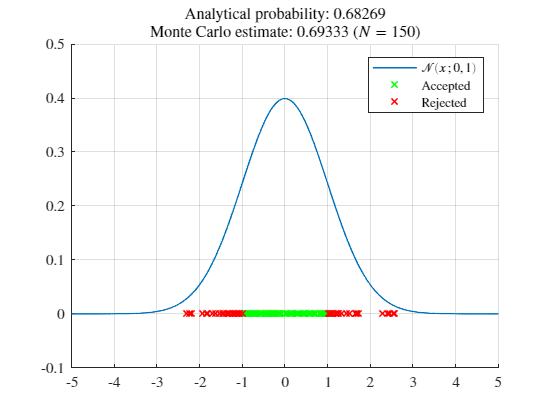

% Change default text interpreters to latex
set(groot, 'defaultTextInterpreter', 'latex');       
set(groot,'defaultAxesTickLabelInterpreter','latex');  
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

% Change default stem line width to 1
set(groot,'defaultStemLineWidth', 1);  

% Change default plot line width to 1
set(groot,'defaultLineLineWidth', 1);    

% Change default scatter line width to 1
set(groot,'defaultScatterLineWidth', 1);    

% Turn x-axis grid on by default
set(groot,'defaultAxesXGrid','on');     

% Turn y-axis grid on by default
set(groot,'defaultAxesYGrid','on');   


 % Adjust default figure window position & size. Window size default: 500 x 375 pixels
set(groot,'defaultfigureposition',[400 250 500 375])

To have these setting run everytime MATLAB starts so you don't have to, you can create a `startup.m` file that MATLAB has in its Path. You can run the following command to access this `startup.m `file, or create it if it doesn't exist.

edit(fullfile(userpath, 'startup.m'))

**Submitting Homeworks & Reports.** After seeing all the ways you can write a nice-looking report as a MATLAB Live Script with a `.mlx` extension, it also makes sense to export it in various formats so that it is computationally much lighter and portable. The most common option will be to export as a `.pdf` file. You can do so by going to "Export" on the toolbar and selecting "Export to PDF...". MATLAB then will run your code once from start to finish, create all the figures (animations are taken at their last frames) and replace controls with whatevery value they have at the time of export, and compile a report for you.

One internal way of exporting is saving your `.mlx` Live Script as a regular `.m` MATLAB script file. When you do, your text will be converted to comment in a way that MATLAB can *publish* that `.m` file in various formats such as `.pdf`, much like exporting a Live Script file. If you do this, you will see that you can also write fancy-looking reports in a `.m` file, only this time you will be *coding* how your texts should look like and can see those modifications after you publish.

## III. MATLAB for Probability Computations

This section focuses on making computations regarding probabilities and random objects. It starts with a presentation of the basic functions and moves on with a brief interlude on handling continuous quantities. It will contain in the future a section about Monte Carlo simulations as well.

### III.1. Functions for Probability

**Sampling from common distributions. **Sampling is one of the most natural things you can do with a probabilistic object. There are a couple of default sampling functions which produce very common random variables, and then there are functions for sampling from custom random distributions that you create.

The most basic three random samplers are

- $U(0,1)$, continuous uniform distribution between 0 and 1:

uniformSample = rand()

- $\mathcal{N}(0\,, 1)$, standard Gaussian with zero mean and unit variance:

stdGaussianSample = randn()

- Random integer from 1 upto N, all equally likely:

integerSample = randi(10)

A way of creating your own finite random objects is via the `randsample()` function. This allows you to sample from a vector (or matrix) with customizable weights that are automatically normalized to 1 (equal weights by default), with or without replacement. You are essentially specifying a probabilit space, with the sample space as a vector (or matrix) and probabilities.

customSamples = randsample(1:10, 3, true, 1./(1:10))

**Evaluating PDFs & CDFs.** There are not that many common pdfs or cdfs that are built-in as stand-alone functions in MATLAB as far as I know. The most commonly used one in my experience is the one belonging to Gaussian distribution: `normpdf()` and `normcdf()`.

x = -5:0.01:5;

tiledlayout(2,1)

nexttile
plot(x, normpdf(x))
title('PDF $f_X(x)$')
ylim([-0.1 0.5])

nexttile
plot(x, normcdf(x))
title('CDF $F_X(x)$')
ylim([0 1.1])

sgtitle('Standard Gaussian $\mathcal{N}(0, 1)$', Interpreter='latex') 

Alternative functions for the CDF of the standard Gaussian are `erf()` and `erfc()`, short for error function. You can refer to their documentation to see how they differ from `normcdf()`.

**Random Seed.** Even though our computers are quite powerful devices, they cannot produce *truly* random objects. We must make do with *pseudorandom* objects which are as close as possible to true randomness using various algorithms, which are tested according to "how random" they are (In fact, generation of random samples in computers is a research area on its own.). MATLAB uses what is called a *seed* that acts like an integer key for the random number generation process. MATLAB sets this seed to `0` by default, and you can set it to any number you like via the `rng()` command (through which you can also change the sampling algorithm). You can see below that I set it to an arbitrary integer, and you will observe that consecutive calls to `rand()` produce the same result. 

rng(5670306)

uniformSample = 0.2321


rand(1,5)'

stdGaussianSample = -0.0037

This can be useful if you want your results to be *exactly* reproducible. But remember, you should always test it with other random seeds at least once to make sure your code works in general and not for that extremely specific/magical set of generated numbers by the seed you provide.

**Recovering Distributions.** Histograms are a very useful tool in summarizing data or estimating the probabilty distribution from the samples of a random variables. They work by counting the number of data points within a certain partition of the underlying space, called bins. MATLAB's `histogram()` function is a very useful function that automates various choices that you have to make while constructing histograms. The `histogram()` can also be configured to estimate distributions by setting the `normalization` property. Notice that `histogram()` is a *plotting function*, meaning it will create a figure whenever it is called.

samples = randsample(1:10, 1000, true, 1./(1:10));

integerSample = 5


figure

customSamples =      6     2     5


sampleHistogram = histogram(samples, ...
    Normalization='count'); % set to 'probability' or 'pdf'
title({['Histogram of samples from my custom random variable'], ...
    ['N = ' num2str(length(samples)) ' samples']})

The `histogram()` function also returns an object, which can be stored in a variable as I am doing above. The properties of this object can be quite useful.

sampleHistogram

**Making a Multifunctional Random Object. **A useful way of creating a random object that comes equipped with various tools to help you out is using the `makedist` function. `makedist` can generate a wide range of random variables, which are listed in its documentation. 

stdGaussian = makedist('Normal', mu=0, sigma=1)

Let's see what methods this new object has.

methods(stdGaussian)

That's nice: I can evaluate its pdf and cdf, as well as observe its variance and mean. I can also sample from it using the `.random` method.

sample = random(stdGaussian) % stdGaussian.random()
pdf_of_sample = stdGaussian.pdf(sample)
cdf_of_sample = stdGaussian.cdf(sample)
stdGaussian.mean()
stdGaussian.var()

### III.2. Handling Continuous Quantities

**The Simplest Function I Know. **Let's calculate the integral of $f(x) = x$, the simplest function I know, from 0 to 1. The result should be $1/2$ from calculus and intuition.

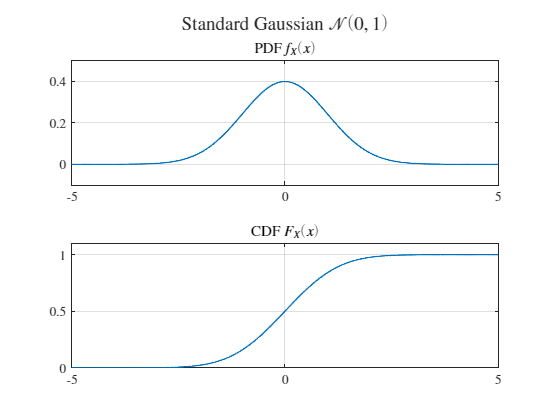

dx = 0.001; % I wonder why I did that...
x = 0:dx:1;

f_x = x;


integral_f = sum(f_x)

What? This is huge! What's wrong with my calculation?

What about the derivative, that should be easy enough: 1.

% diff() is the closest thing to differentiation you can find in MATLAB. 
% Check the documentation for more info.
f_prime_x = diff(x); 


ans =     0.0707
    0.1991
    0.7447
    0.0207
    0.7129


figure
plot(x(2:end), f_prime_x) % diff decreases the length of the vector by 1
ylim([0 max(f_prime_x)*2])
title(["Derivative of $f(x) = x$"; "It should be $f'(x) =1$, but I wonder if it will be..."])
xlabel('x')

Why isn't this giving me 1?

**Solution to both. **MATLAB is discrete in nature, so handling "continuous operations" requires some attention. For the integration let's go back to the Riemann integral: We have


$$\int_A f(x) dx \approx \sum_{P_i \in \mathcal{P}} f(x^*_i) \Delta x_i \quad \text{where}\quad x^*_i \in P_i\,, \Delta x_i = |P_i|\,, \bigsqcup P_i = A$$


for some sufficiently fine partition of the integration region. We want to have the LHS, but must make do with the RHS: My integration is missing the $\Delta x$ term, so it's like I multiplied the actual approximation to the integral by $\frac{1}{\Delta x}$, that's why I obtain approximately 


$$\frac{1/2}{0.001}= 500$$


The same logic goes for differentiation as well. Let's go back to the limit definition: I want 


$$f'(x_0) = \lim_{\Delta x \to 0} \frac{f(x_0 + \Delta x) - f(x_0)}{\Delta x}$$


but have to settle with a "finitely small" $\Delta x$ term that I *have to include*: 


$$f'(x_0) \approx \frac{f(x_0 + \Delta x) - f(x_0)}{\Delta x}$$


So, let's correct my mistakes.

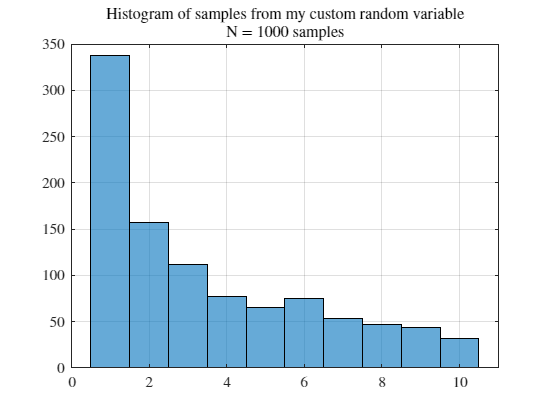

integral = sum(f_x) * dx
f_prime_x = diff(x) / dx;

figure
plot(x(2:end), f_prime_x)

ylim([0 max(f_prime_x)*2])
title(["Derivative of $f(x) = x$"; "Now it is $f'(x) = 1$, so everything is fine"])

sampleHistogram =   Histogram with properties:

             Data: [1 1 2 1 1 1 4 6 1 5 3 5 3 1 3 10 2 1 1 1 10 1 2 1 4 1 2 2 1 10 3 5 10 8 7 2 5 2 1 1 2 2 5 2 5 1 1 2 1 1 2 3 4 4 5 6 5 5 3 4 1 1 3 6 2 5 2 1 1 1 3 1 3 2 2 6 9 5 3 7 1 6 1 2 2 5 7 1 4 3 3 5 1 2 5 6 7 2 1 8 1 3 7 1 1 4 3 10 3 1 1 6 1 … ]
           Values: [338 157 112 77 65 75 53 47 44 32]
          NumBins: 10
         BinEdges: [0.5000 1.5000 2.5000 3.5000 4.5000 5.5000 6.5000 7.5000 8.5000 9.5000 10.5000]
         BinWidth: 1
        BinLimits: [0.5000 10.5000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


xlabel('x')

A good question to ask at this point is, how should one choose `dx`? Ideally, it should be as small as possible, but that may not be possible for several reasons:

- Having `dx` extremely small will result in *immense *vectors, and your computer (being finite) cannot be able to store such large data.

- Your computer also has finite precision, meaning it has a certain representative power restricting how large or small numbers it can operate with. It most likely cannot even create or has an appropriate representation for the real number $10^{-12345678123456879435135469879543682}$.

- Even if you can create such large arrays and such small values, you may risk computational stability of your results.

- Finally, even if you dodhge *all* of these problems, your computer can take an *amazingly* long time to finish computation.

### III.3. Monte Carlo

**Parameter estimation example: Success probability of a Bernoulli R.V.** You have seen in the class that you can estimate the probability of success of a Bernoulli random variable with a quite intuitive estimator: Get $N$ samples, sum them up, and divide by $N$. Let's see this estimator in action.

I start by taking my iid. Bernoulli samples.

p = 0.42;  

stdGaussian =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


N = 2000;


Methods for class prob.NormalDistribution:

cdf        gather     icdf       iqr        mean       median     negloglik  paramci    pdf        proflik    random     std        truncate   var        



data = randsample([0 1], N, true, [1-p p]);

Now that I have my samples, I will plot the trajectory of estimation: I run my estimator with the first $n$ samples as $n$ varies from 1 to $N$.

p_est_ = zeros(size(data)); 

sample = -0.8898

pdf_of_sample = 0.2685

for n = 1:N

cdf_of_sample = 0.1868

ans = 0

    p_est_(n) = sum(data(1:n)) / n; % Estimator running with the first n samples

ans = 1


end

figure
hold on
plot(1:N, p_est_)
plot(1:N, p*ones(size(data)), '--')
legend( 'Estimator Result', 'Ground Truth',...
    Location='best', Interpreter='latex')

integral_f = 500.5000

ylim([0 1]); xlim([1 N]);
title({'Estimator Performance vs. Nr. of Samples', ...
    ['$p_{true} = ' num2str(p, '%.2f') '$ \& $p_{est} = ' num2str(p_est_(end), '%.2f') '$']})

Running this section again yields different estimation trajectories because the dataset changes. Let's visualize multiple trajectories at once and see that different trajectories converge to the actual $p$ value as expected.

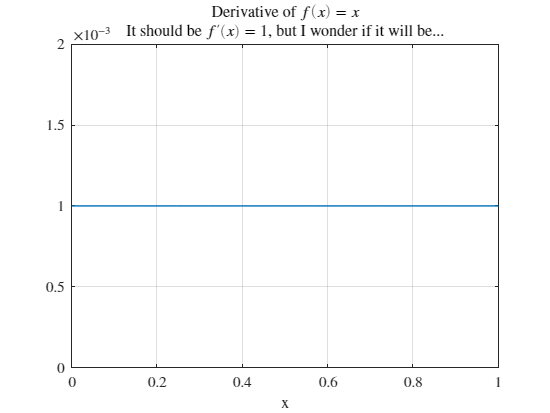

figure
hold on
ylim([0 1])

K = 20; % Number of trajectories

labels = cell(K,1); % To set the legend more easily


for k = 1:K

    labels{k} = '';

    p = 0.26;
    N = 10000;

    data = randsample([0 1], N, true, [1-p p]);
    
    p_est_ = zeros(size(data)); 
    

integral = 0.5005

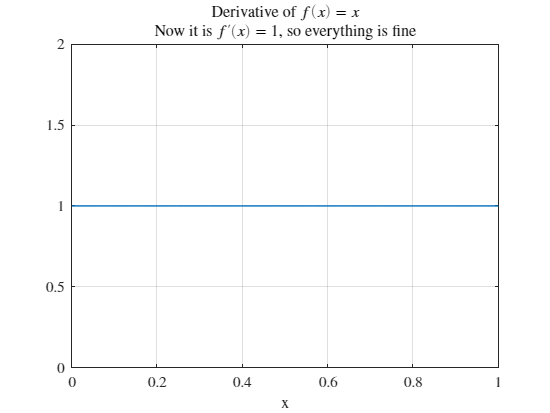

    for n = 1:N
        
        p_est_(n) = sum(data(1:n)) / n;
    
    end

    plot(1:N, p_est_, 'b', Color=[0.7 0.7 1]);


end

labels{1} = 'Sample Trajectories';
labels{K+1} = 'Ground Truth';

plot(1:N, p*ones(size(data)), 'k--')

ylim([0 1])
title([num2str(K) ' Different Estimator Trajectories'])
legend(labels, ...
    Interpreter='latex', Location='best')

**Probability estimation example: Confirming the Gaussian 1-**$\sigma$ **interval probability. **A basic example of estimation a probability using Monte Carlo: Let's check the samples of a standard Gaussian r.v. fall within the 1-$\sigma$ range.

P_1sigmaRange_analytical = normcdf(1) - normcdf(-1)

Let's check this result by sampling from the standard normal distribution:

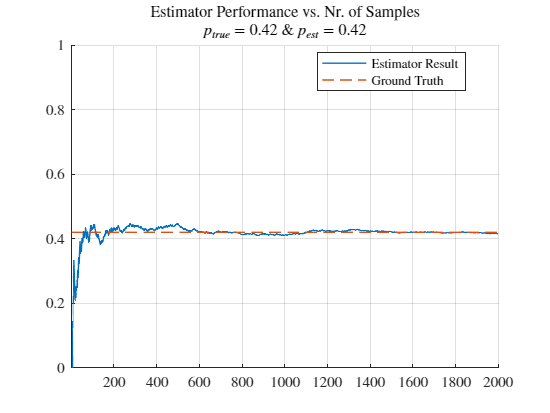

N_samples = 28870;  

samples = randn(N_samples, 1);

samples_in = samples(abs(samples) < 1);
samples_out = samples(abs(samples) >= 1);

P_1sigmaRange_MC = length(samples_in) / length(samples)

Some visualization is always nice.

x = -5:0.01:5;

figure
hold on
plot(x, normpdf(x))
scatter(samples_in, zeros(size(samples_in)), 'gx')
scatter(samples_out, zeros(size(samples_out)), 'rx')
legend('$\mathcal{N}(x\,; 0, 1)$', 'Accepted', 'Rejected', Interpreter='latex', Location='best')
title({['Analytical probability: ' num2str(P_1sigmaRange_analytical, '%.5f')], ...
       ['Monte Carlo estimate: ' num2str(P_1sigmaRange_MC, '%.5f') ' ($N = $' num2str(N_samples) ')']})
xticks(-5:1:5)

**Passing samples through their own CDF.** Suppose we take a sample $X \sim f_X(x)$ from a continuous random variable, where $f_X(x)$ denotes the (continuous) PDF and $F_X(x)$ denotes the CDF. Now, we know theoretically that if we pass the sample $X$ through its own CDF to obtain a new random variable $F_X(X)$, this new random variable will be distributed uniformly between 0 and 1, i.e.


$$F_X(X) \sim U(0,1)$$


Let's try to form some intuition around this interesting fact. First, let's confirm this interesting fact via Monte Carlo using an exponential distribution.

N = 100000;

exp_rv = makedist('Exponential', mu=1);
samples = exp_rv.random(N,1);

Visualize the PDF and the samples.

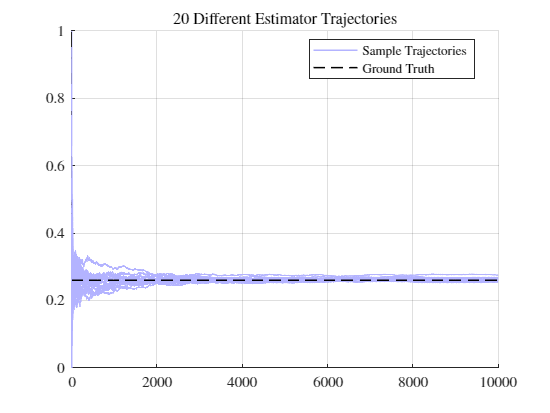

x = 0:0.01:(ceil(max(samples)/2)*2); % Make the grid adaptible to the samples I am taking

figure
hold on

plot(x, exp_rv.pdf(x))
plot(x, exp_rv.cdf(x))
scatter(samples, zeros(size(samples)) - max(exp_rv.pdf(x))*0.1, '.')

P_1sigmaRange_analytical = 0.6827

legend('$f_X(x)$', '$F_X(x)$', '$X \sim f_X$', ...
    Location='best', ...
    Interpreter='latex')
title({'Exponential Distribution with $\lambda = 1$', '$f_X(x) = \lambda e^{-\lambda x}$ for $x \geq 0$'})
ylim([-0.2 1.2])
xlim([0 max(x)])

Now let's pass the samples through the CDF and make a histogram out of them. I set the `histogram()` to not counting but to estimating the PDF.

figure
histogram(exp_rv.cdf(samples), ...
    Normalization="pdf")

P_1sigmaRange_MC = 0.6848

title({'Monte Carlo PDF estimate of $F_X(X)$', ['with $N = 10^' num2str(log10(N)) '$ samples']})
ylim([0 1.5])

Now that we have confirmed the theoretical result by Monte Carlo, let's try to form some more intuition around this peculiar result.

I want to take a look at the difference of samples in the first and last tenths of the samples, and the difference between them.

sorted_samples = sort(samples);

first_tenth = sorted_samples([1 (N/10)]);
first_tenth_diff = diff(first_tenth)
last_tenth = sorted_samples([(N*9/10) N]);
last_tenth_diff = diff(last_tenth)

There is quite a difference. Now let's see what happens to this difference *after* I pass them through the CDF.

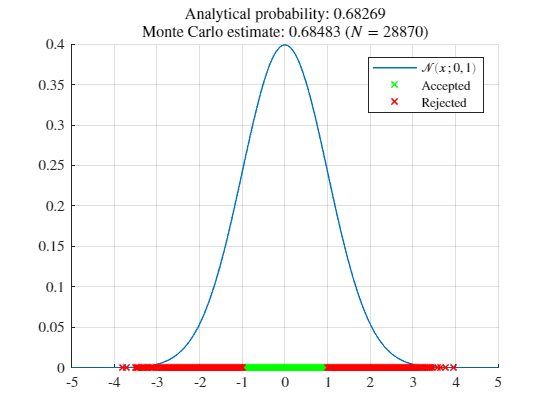

first_tenth_afterCDF = exp_rv.cdf(first_tenth);
first_tenth_afterCDF_diff = diff(first_tenth_afterCDF)
last_tenth_afterCDF = exp_rv.cdf(last_tenth);

last_tenth_afterCDF_diff = diff(last_tenth_afterCDF)

There doesn't seem to be that much of a difference now! In fact, they are quite close. How is this the case?

Let's go back to the PDF and the CDF, and plot all of our results so far on a single plot. This will take some work, but it will be a good summary of our results.

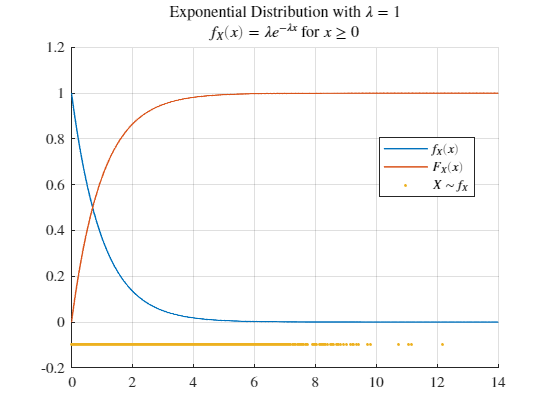

f = figure;

hold on
ylim([-0.5 2])
xlim([-2 max(x)])

% PDF and CDF
plot(x, exp_rv.pdf(x))
plot(x, exp_rv.cdf(x))

% Now the new stuff
plot(first_tenth, zeros(size(first_tenth))-0.25, 'bx-')
plot(last_tenth, zeros(size(last_tenth))-0.25, 'bx-')
plot(zeros(size(first_tenth_afterCDF))-1, first_tenth_afterCDF, 'rx-')
plot(zeros(size(last_tenth_afterCDF))-1, last_tenth_afterCDF, 'rx-')

plot([first_tenth(1) first_tenth(1) -1], ...
     [-0.2 first_tenth_afterCDF(1) first_tenth_afterCDF(1)], ...

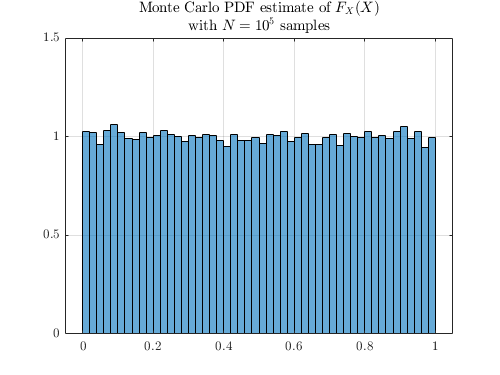

    'k:', LineWidth=0.1)
plot([first_tenth(2) first_tenth(2) -1], ...
     [-0.2 first_tenth_afterCDF(2) first_tenth_afterCDF(2)], ...
    'k:', LineWidth=0.1)
plot([last_tenth(1) last_tenth(1) -1], ...
     [-0.2 last_tenth_afterCDF(1) last_tenth_afterCDF(1)], ...

    'k:', LineWidth=0.1)
plot([last_tenth(2) last_tenth(2) -1], ...
     [-0.2 last_tenth_afterCDF(2) last_tenth_afterCDF(2)], ...
    'k:', LineWidth=0.1)

% Informative stuff

first_tenth_diff = 0.1032

legend('$f_X(x)$', '$F_X(x)$', 'Before CDF', '', 'After CDF', '', ...
    Location='best', ...

last_tenth_diff = 9.8739

    Interpreter='latex')
title({'Exponential Distribution with $\lambda = 1$', ...
    'First and last 10$^{th}$ samples passed through the CDF'})

first_tenth_afterCDF_diff = 0.0980

The regions where the samples are more dense are indicated by a high PDF value, which in turn makes the CDF have a *higher slope* around that area. This higher slope means that the samples at *higher-density regions are separated more by the CDF.* Conversely, the regions where we have sparser samplesa are indicated by a low PDF value which in turn makes the CDF have a *lower slope* around that area. This lower slope means that the samples at lower*-density regions are separated less by the CDF.* This readjustment of the distances between samples is done so perfectly by the CDF that the effects of dense sampling-more separation and sparse sampling-less separation cancel each other *perfectly,* yielding the uniform distribution between 0 and 1.

**Histogram Equalization. **What to make of the above result that we have just confirmed? One application of it in the image processing field is *histogram equalization.* (The sample images and the functions imread()` and imshow()` require the [Image Processing Toolbox](https://www.mathworks.com/products/image.html).)

Suppose we have the following image.

originalImage = double(imread('pout.tif')); % Read image, cast entries as double
originalImage(1:5, 1:5)

last_tenth_afterCDF_diff = 0.0998

We can see that the whole image is represented in MATLAB as a matrix, whose entries are pixel illumination intensities. Normally, this value ranges from 0 to 255. Now, let's actually look at the image.

figure
imshow(originalImage, [0 255]) % Because entries are double, specify the display range

You can see that the image is quite low in contrast, which can become a problem when one does image processing (e.g. feature detection). Let's quantify this lowness of contrast, by checking the histogram of the pixel values. We will set `histogram()` to estimate the PDF of the pixel intensity distribution, over bins of unit width so that each bin corresponds to a single pixel intensity value. We also estimate the CDF, because we will need it later on.

figure
tiledlayout(2,1)

nexttile
poutHist = histogram(originalImage, ...
    BinEdges=-0.5:255.5, ...
    Normalization='pdf');
xticks(0:32:256)
title('PDF Estimate')

nexttile
poutCDFHist = histogram(originalImage, ...
    BinEdges=-0.5:255.5, ...
    Normalization='cdf');
xticks(0:32:256)
title('CDF Estimate')

sgtitle('Original Image', Interpreter='latex')

The reduced image contrast presents itself in the image histogram quite visibly: All of the pixel intensities are accumulated in quite a narrow region, indicating that the illumination values are quite similar to one another. 

Histogram equalization aims to separate out these pixel intensity values in such a way that the image information is still preserved, but the full dynamic range of 0 to 255 is used. To do this, the idea of passing random samples through their own CDF is used, which is why we estimated the CDF above. We treat the pixel intensities to be samples from the distribution that we estimated through the histograms, and adjust their values according to the CDF values we estimate. The loop below is nothing more than applying this CDF transformation to create a new image matrix equalizedImage, only set values are adjusted to be integers from 0 to 255 to again have an image of the same format. Notice that this has no effect on the uniformity of the newly obtained samples, only their range is not the unit interval but from 0 to 255 (we can also round the numbers to have integers again).

equalizedImage = zeros(size(originalImage));

for i = 0:255

    equalizedImage(originalImage == i) = poutCDFHist.Values(i+1) * 255;

end

Let's see how the equalized image looks like.

figure
imshow(equalizedImage, [0 255])

As you can see, the image information is well-preserved (at least by visual inspection), but the contrast is much better. Let's check the histograms again, to observe the change in distribution. I animate it over a range of `BinEdges` vectors.

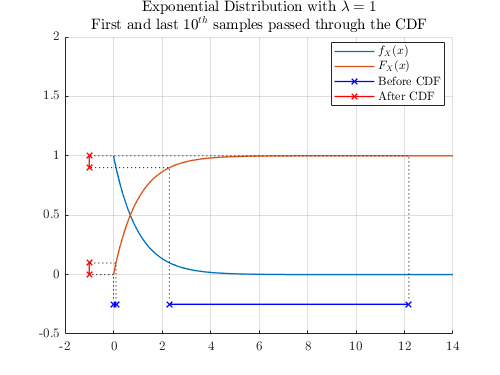

animFig = figure();


for binWidth = 2.^(0:7)

    figure(animFig)
    tiledlayout(2,1)
    
    nexttile

ans =    107   108   107   106    99
   109   106   108   107   103
   107   106   110   110   106
   106   107   108   108   108
   105   108   109   109   108


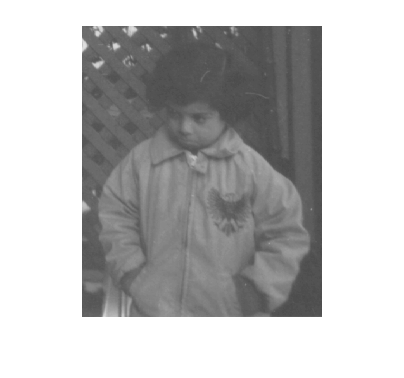

    normalizedPoutHist = histogram(equalizedImage, ...
        BinEdges=-0.5:binWidth:255.5, ...
        Normalization='pdf');

    xticks(0:32:256)
    title('PDF Estimate')
    
    nexttile
    normalizedPoutCDFHist = histogram(equalizedImage, ...
        BinEdges=-0.5:binWidth:255.5, ...
        Normalization='cdf');
    xticks(0:32:256)
    title('CDF Estimate')
    
    sgtitle(['Equalized Image, Histograms with \texttt{binWidth = ' num2str(binWidth) '}'], ...
        Interpreter='latex')

    pause(2)

end

You can see that for all the `binWidth` values, the CDF has the ramp characteristic of a uniform random variable. For `binWidth = 1`, we can see that the new histogram is quite similar to the original one with the same peaks and valleys in bin values, only the histogram bins are separated out. As we increase the `binWidth` value, we can see that this separation is such that the bin heights get closer and closer to one another, as we would expect from the samples of a uniform random variable.

## Appendix A. Function Declarations

### A.1. iid. Bernoulli Sampler

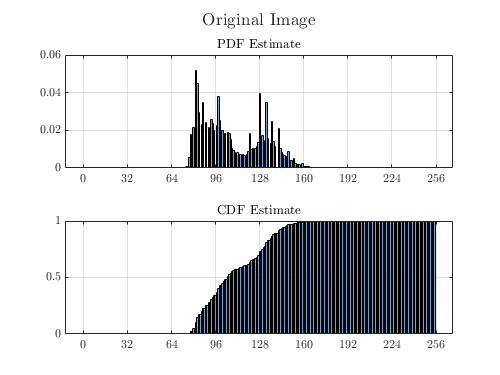

function [samples] = Bernoulli(N, p)
%Bernoulli returns N iid. samples from the Bernoulli distribution with 
% probability of success p.

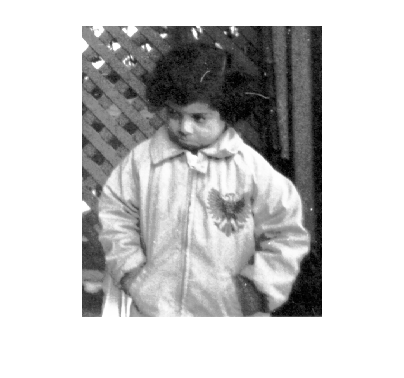

%   
%   Bernoulli() returns a single sample with p = 0.5. The default value for
%   N is 1.
%   Bernoulli(N) returns a Nx1 vector of iid. samples with p = 0.5. The 
%   default value for p is 0.5.
%   Bernoulli(N, p) returns Nx1 vector of iid. samples with p.

    switch nargin
        case 1
            p = 0.5;
        case 0
            p = 0.5;

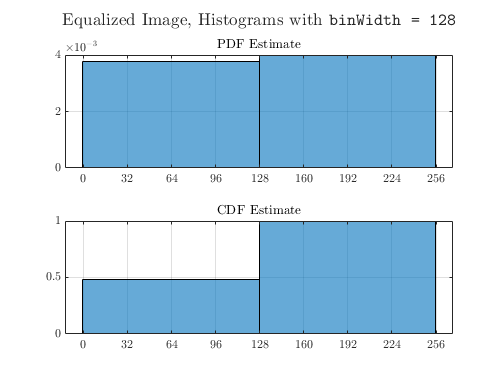

            N = 1;
        otherwise
    end

    samples = rand(N, 1);
    samples = (samples <= p);

end